%Single Molecule Trajectory Binarizer

% Authors: Connor Thomas, Srijit Mukherjee

%JILA, Boulder, CO - 80309

Section 1

RawTraces=E3Negative(:,:); % Picks a preimported dataset. Dataset should have Frame # as the first column
H=height(RawTraces);
W=width(RawTraces);
RawTraces=table2array(RawTraces);
x=RawTraces(:,1);
Displaytraces = [10,9,8,7,6,5,4,3] %Fill in the #s of 8 traces you would like to look at

Displaytraces =     10     9     8     7     6     5     4     3


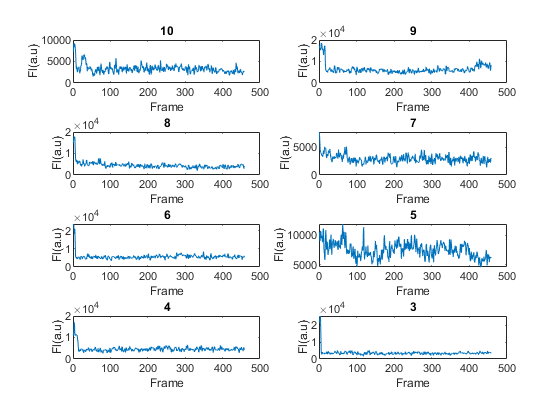


for a = 1:8 % Plots 8 traces for viewing. At least 5 on times must be manually identified
    subplot(4,2,a)
    plot(x,RawTraces(:,Displaytraces(a)))
    title(Displaytraces(a))
    ylabel('Fl(a.u)');
    xlabel('Frame')
end


RawTraces=array2table(RawTraces);
traces = figure();
clf

Section 2

Defines selected "On" time and displays it and associated stats


ChosenOnes =  [  5, 5, 5, 5, 5] % Chosen Blinks - Maintain same order throughout

ChosenOnes =      5     5     5     5     5


BlinksStart = [ 261, 261, 262, 264, 265] %Start of on time -Frame Number (Can't be 0)

BlinksStart =    261   261   262   264   265


BlinksEnd =   [ 299, 299, 298, 297, 295] % Ending Number

BlinksEnd =    299   299   298   297   295


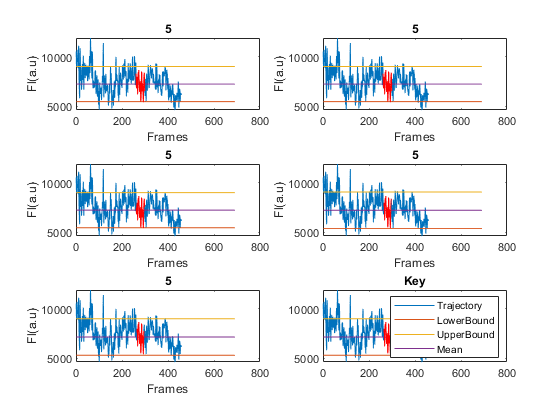

%Try to pick traces with clear on times that aren't significantly higher
%than other blinks (i.e. potential multi fluorophore events)

Mean= zeros(1,5);
SD= zeros(1,5);
LowB= zeros(1,5);
UpB= zeros(1,5);

for a=1:5 %Run stats on selected on times.
    chosen = table2array(RawTraces(:,ChosenOnes(a)));
    blinkduration = linspace(BlinksStart(a),BlinksEnd(a),BlinksEnd(a)-BlinksStart(a)+1);
    Samblink = (0);
    SamBlink=table2array(RawTraces(BlinksStart(a):BlinksEnd(a),ChosenOnes(a)));
    Mean(a)=mean(SamBlink);
    SD(a)=std(SamBlink);
    LowB(a)=Mean(a)-2*SD(a);%Segments above this value are considered "on" during that time
    UpB(a)=Mean(a)+2*SD(a); %Segments above this value are considered multiprotein and the offending trace removed from analysis
    Meana= linspace(Mean(a),Mean(a),numel(x));%Makes lines for plotting bounds
    LowBa= linspace(LowB(a),LowB(a),numel(x));
    UpBa= linspace(UpB(a),UpB(a),numel(x));

    subplot(3,2,a) %The selected on time is shown in red. The lower bound should be high enough to distinguish between an on and an off event (i.e above background)
    plot(x,chosen,x,LowBa,x,UpBa,x,Meana,blinkduration,SamBlink,'red')
    ylabel('Fl(a.u)');
    xlabel('Frames')
    title(ChosenOnes(a))
end
subplot(3,2,6) %Plots a key with a legend to make sure all other plots are legible
plot(x,chosen,x,LowBa,x,UpBa,x,Meana,blinkduration,SamBlink,'red')
legend('Trajectory','LowerBound','UpperBound','Mean')

title("Key")


MeanAr =Mean %Shows the means of each selected on time. Should all probably be comparable

MeanAr = 	1.0e+03 *

    7.2572    7.2572    7.2479    7.2441    7.1607


SDAr = SD

SDAr =   890.7261  890.7261  890.1557  923.9419  921.8576


LowBAr = LowB %Boundary values, by their associated reference trace

LowBAr = 	1.0e+03 *

    5.4757    5.4757    5.4676    5.3962    5.3169


UpBAr = UpB

UpBAr = 	1.0e+03 *

    9.0387    9.0387    9.0283    9.0920    9.0044


UpB = 0;
LowB = 0;
RawTrM=RawTraces{:,:}; % Converts the table to a Matrix
TrajAve=sum(sum(RawTrM(:,2:end)))/((W-1)*H) %Average of entire dataset for comparison

TrajAve = NaN

clf

Section 3

Extracts noise of dataset and fits it 

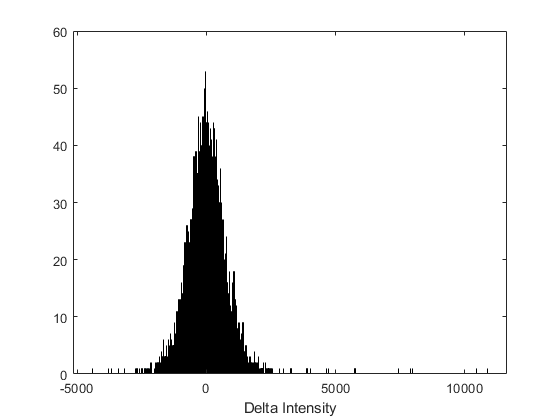

DeltaI=RawTrM(1:end-1,2:end)-RawTrM(2:end,2:end); %Finds difference in intensity between every consecutive frame in the dataset

B=DeltaI(DeltaI~=0); %Histograms noise, removes any zero values to avoid a large peak @ zero
h=histogram(B,1500,'BinLimits',[min(B),max(B)]); %Always makes 1500 bins, size varies based on noise spread
xlabel('Delta Intensity')

counts=h.Values.';


x3=[min(B):((max(B)-min(B))/1499):max(B)].';
x3=x3(counts~=0); 
counts=counts(counts~=0); 
[NoiseFit,gofnoise] = fit(x3,counts,'gauss1') %Displays fit for noise and goodness of fit stats

NoiseFit =      General model Gauss1:
     NoiseFit(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =       38.32  (37.45, 39.18)
       b1 =      -3.783  (-19.83, 12.27)
       c1 =       868.1  (845.4, 890.9)

gofnoise = struct with fields:
           sse: 5.9082e+03
       rsquare: 0.9266
           dfe: 426
    adjrsquare: 0.9263
          rmse: 3.7241


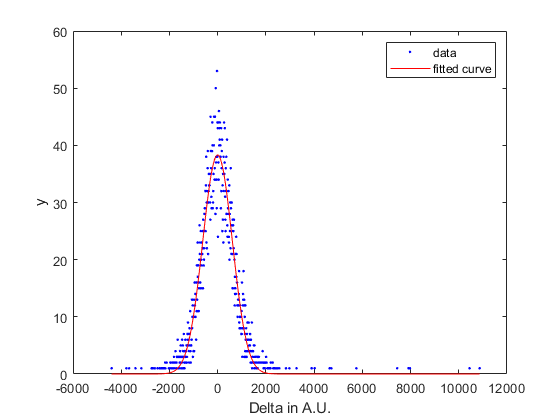

plot(NoiseFit,x3,counts) %Plots noise fit
xlabel('Delta in A.U.')

coeffNoise=coeffvalues(NoiseFit);

Section 4

Identifies state changes and binarizes based on them

Fmean=coeffNoise(1,2); %Finds values of noise fit
FSD=coeffNoise(1,3)/(2^(1/2));
FLB=Fmean-1.5*(FSD) %Frames that change by more than one of the bounds are considered points of interest

FLB = -924.5589

FUB=Fmean+1.5*(FSD) %Points of interest are possible state changes

FUB = 916.9932

Points=zeros(1,W);%Where points will be stored
for k=1:1:W-1 %Checks for frames where change is larger than the bounds
     FrameNum=1;
    for l=1:1:H-1
        if DeltaI(l,k)>=FUB
            Points(FrameNum,k)=l;
            FrameNum=FrameNum+1;
        elseif DeltaI(l,k)<=FLB
            Points(FrameNum,k)=l;
            FrameNum=FrameNum+1;
        else
        end
    end
end
ExperimentBins=zeros(H,W-1);
A=mat2dataset(Points);
A=dataset2table(A);
H2=height(A);

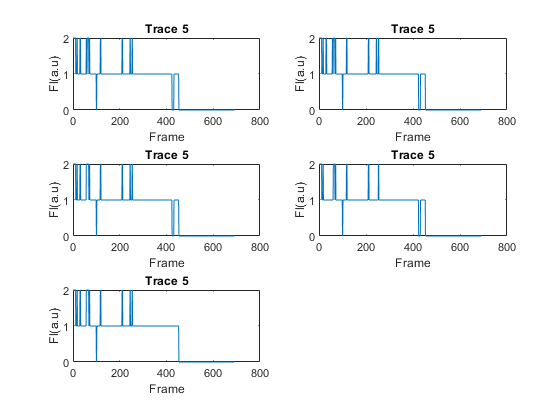

%Section 5: Binarized trace storage
savedtraces = cell(1,5); %Where extracted on times,off times and binarized traces will be stored
savedontimes = cell(1,5);
savedofftimes = cell(1,5);
for a=1:5
    UpB = UpBAr(a);
    LowB = LowBAr(a);
for k=1:1:W-1 %Actually binarizes
    for l=1:1:H2 %Checks between every point of interest and finds the average between them
        POI=Points(l,k); % Compares averages to the bounds set by selected trace 
        POI2=0; %If it is below the low bound = 0
        if l~=1 % Above the upper bound =2
        POI2=Points(l-1,k); % Otherwise = 1
        end
        if l==1
            Section=RawTrM(1:POI,k+1);
            SectionMean=mean(Section);
            if SectionMean>UpB
                ExperimentBins(1:POI,k)=2;
            elseif SectionMean<LowB
                ExperimentBins(1:POI,k)=0;
            else
                ExperimentBins(1:POI,k)=1;
            end
        elseif POI==0 && POI2~=0
            Section=RawTrM(POI2:H,k+1);
            SectionMean=mean(Section);
            if SectionMean>UpB
                ExperimentBins(POI2:H,k)=2;
            elseif SectionMean<LowB
                ExperimentBins(POI2:H,k)=0;
            else
                ExperimentBins(POI2:H,k)=1;
            end
        elseif POI==0
        else 
            Section=RawTrM(POI2:POI,k+1); 
             SectionMean=mean(Section);
            if SectionMean>UpB
                ExperimentBins(POI2:POI,k)=2;
            elseif SectionMean<LowB
                ExperimentBins(POI2:POI,k)=0;
            else
                ExperimentBins(POI2:POI,k)=1;
            end
        end
    end
end
for k=1:1:W-1 %Checks for and sets any 1 frame events to neighboring values
    for l=1:1:H % i.e. 1110111 = 1111111
        if l==1
        elseif l==H
        elseif ExperimentBins(l,k)~=ExperimentBins(l-1,k) && ExperimentBins(l-1,k)==ExperimentBins(l+1,k)
        ExperimentBins(l,k)=ExperimentBins(l-1,k);
        end
    end
end
TS=ExperimentBins(:,ChosenOnes(a)-1); %Shows each chosen trace binarized based on that traces metrics
subplot(3,2,a)
plot(x,TS);
title(['Trace ', num2str(ChosenOnes(a))])
ylabel('Fl(a.u)');
xlabel('Frame')



% Section 6
% Throws out multi protein events and extracts on and off times
TraceNum=1;
TraceNums = zeros(1,5);
SelectBlinks =[];
for k=1:1:W-1
    if max(ExperimentBins(:,k))==1
        SelectBlinks(:,TraceNum)=ExperimentBins(:,k);
        TraceNum=TraceNum+1;
    else
    end
end
TraceNum=TraceNum-1;
OffNum=1;
OnNum=1;
Ontime=0;
Offtime=0;
for k=1:1:TraceNum
    for l=1:1:H
if l==1 && SelectBlinks(l,k)==1
    Ont=1;
elseif l==1 && SelectBlinks(l,k)==0
    Offt=1;
elseif SelectBlinks(l,k)==1 && SelectBlinks(l-1,k)==0
    Offtime(OffNum,1)=Offt;
    OffNum=OffNum+1;
    Ont=1;
elseif SelectBlinks(l,k)==0 && SelectBlinks(l-1,k)==1
    Ontime(OnNum,1)=Ont;
    OnNum=OnNum+1;
    Offt=1;
elseif SelectBlinks(l,k)==1 
    Ont=Ont+1;
elseif SelectBlinks(l,k)==0
    Offt=Offt+1;
end
    end
end
SelectBlinks = logical(SelectBlinks);
TraceNums(a)=TraceNum;
savedtraces{a} = SelectBlinks;
savedontimes{a} = Ontime;
savedofftimes{a} = Offtime;
end

TraceNums 

TraceNums =      0     0     0     0     6


Binned =figure();
clf

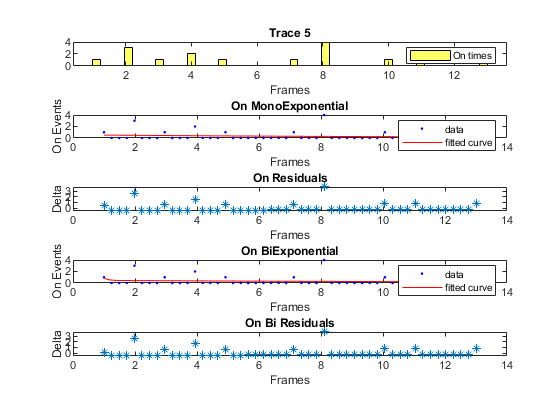

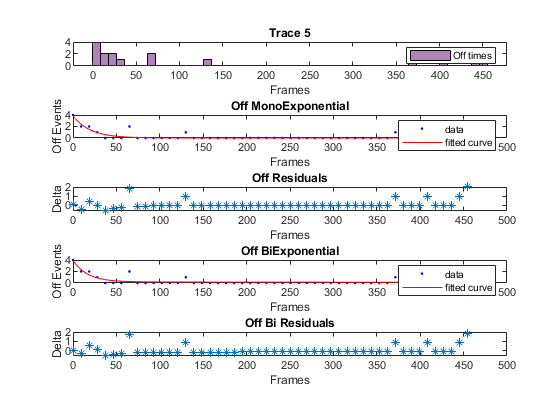

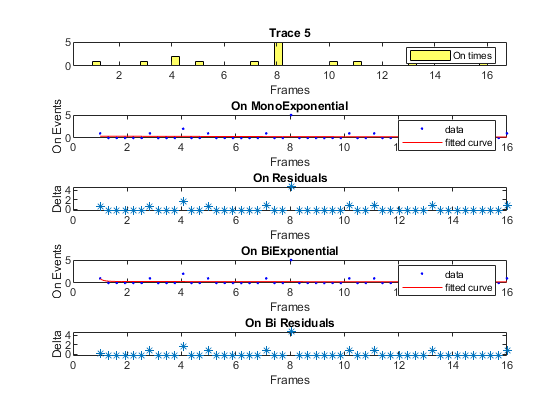

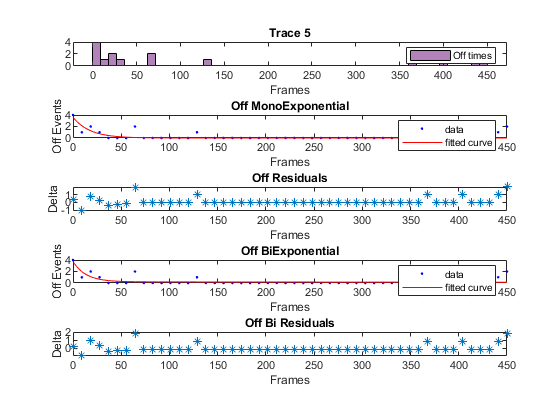

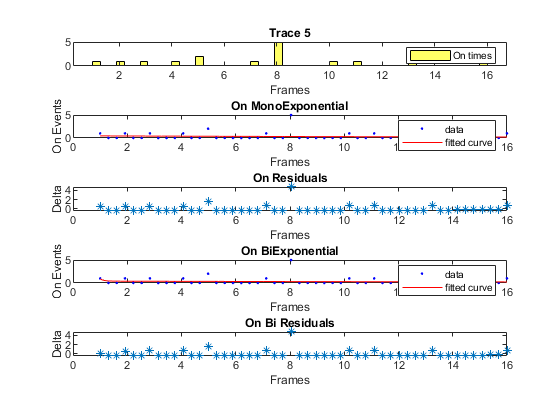

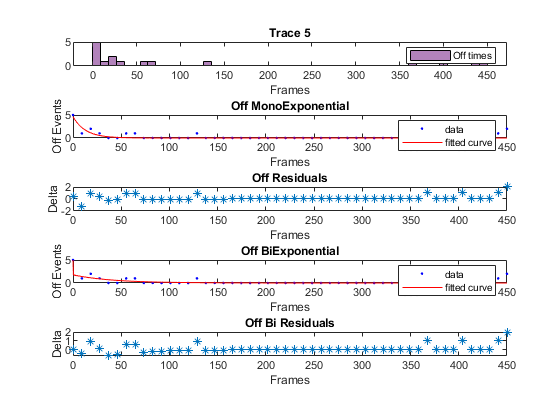


%Section 6
% Fits on and off times to mono and biexpoential fits and reports relevant stats
% If fits are not converging, starting values can be changed
Fitinfo = cell(6,8);
Fitinfo{6,1} = "Onfit";
Fitinfo{6,2} = "OnStats";
Fitinfo{6,3} = "Bionfit";
Fitinfo{6,4} = "BiOnStats";
Fitinfo{6,5} = "Offfit";
Fitinfo{6,6} = "OffStats";
Fitinfo{6,7} = "BioffFit";
Fitinfo{6,8} = "Bioffstats";
OnOffRatio=zeros(5,3);

for a=1:5
    Ontime = cell2mat(savedontimes(a));
    Offtime = cell2mat(savedofftimes(a));
[~,edges] = histcounts(Ontime,50);

subplot(5,1,1)
h=histogram(Ontime,50,'FaceColor','yellow');
title(['Trace ', num2str(ChosenOnes(a))])
legend('On times')
xlabel('Frames')

xfit = fittype('a*exp(-u/t)','independent','u');
fo = fitoptions(xfit);
fo.Lower = [0 0];
xfit = fittype('a*exp(-u/t)','independent','u','options',fo);
startPoints = [20, 20]; %Start Points for On mono fit
counts=h.Values.';
x3=[edges(1,1):((edges(1,51)-edges(1,1))/49):edges(1,51)].';
[Onfit,OnStats]=fit(x3,counts,xfit,'Start',startPoints);

subplot(5,1,2)
plot(Onfit,x3,counts)
title('On MonoExponential')
xlabel('Frames')
ylabel('On Events')
onfunc= Onfit.a*exp(-x3/Onfit.t);
onresid=counts-onfunc;
subplot(5,1,3)
plot(x3,onresid,'*')
title('On Residuals')
xlabel('Frames')
ylabel('Delta')

bifit = fittype('a*exp(-u/t)+b*exp(-u/t2)','independent','u');
bifo = fitoptions(bifit);
bifo.Lower = [0 0 0 0];
bifo.Upper = [1000,1000,1000,1000];
bifit = fittype('a*exp(-u/t)+b*exp(-u/t2)','independent','u','options',bifo);
bistartPoints = [30, 12, 1, 50]; %Start Points for On bi fit
[biOnfit,biOnStats]=fit(x3,counts,bifit,'Start',bistartPoints);


subplot(5,1,4)
plot(biOnfit,x3,counts)
title('On BiExponential')
xlabel('Frames')
ylabel('On Events')
bionfunc= biOnfit.a*exp(-x3/biOnfit.t)+biOnfit.b*exp(-x3/biOnfit.t2);
bionresid=counts-bionfunc;
subplot(5,1,5)
plot(x3,bionresid,'*')
title('On Bi Residuals')
xlabel('Frames')
ylabel('Delta')
On =figure();
clf
OnLT=(biOnfit.a*biOnfit.t+biOnfit.b*biOnfit.t2)/(biOnfit.a+biOnfit.b);
PercentFast=(biOnfit.a/(biOnfit.a+biOnfit.b))*100;
PercentSlow=(biOnfit.b/(biOnfit.a+biOnfit.b))*100;

[N,edges] = histcounts(Offtime,50);
subplot(5,1,1)
h=histogram(Offtime,50,'FaceColor','#7E2F8E');
title(['Trace ', num2str(ChosenOnes(a))])
legend('Off times')
xlabel('Frames')

counts=h.Values.';
x3=[edges(1,1):((edges(1,51)-edges(1,1))/49):edges(1,51)].';
startPoints = [40, 20]; %Start Points for Off mono fit
[Offfit,OffStats]=fit(x3,counts,xfit,'Start',startPoints);

subplot(5,1,2)
plot(Offfit,x3,counts)
title('Off MonoExponential')
xlabel('Frames')
ylabel('Off Events')
offfunc= Offfit.a*exp(-x3/Offfit.t);
offresid=counts-offfunc;

subplot(5,1,3)
plot(x3,offresid,'*')
title('Off Residuals')
xlabel('Frames')
ylabel('Delta')

bistartPoints = [75, 3, 20, 60]; %Start Points for Off bi fit
[biOfffit,biOffStats]=fit(x3,counts,bifit,'Start',bistartPoints);


subplot(5,1,4)
plot(biOfffit,x3,counts)
title('Off BiExponential')
xlabel('Frames')
ylabel('Off Events')
biofffunc= biOfffit.a*exp(-x3/biOfffit.t)+biOfffit.b*exp(-x3/biOfffit.t2);
bioffresid=counts-biofffunc;

subplot(5,1,5)
plot(x3,bioffresid,'*')
title('Off Bi Residuals')
xlabel('Frames')
ylabel('Delta')

Off =figure();
clf

OffLT=(biOfffit.a*biOfffit.t+biOfffit.b*biOfffit.t2)/(biOfffit.a+biOfffit.b);
PercentFastoff=(biOfffit.a/(biOfffit.a+biOfffit.b))*100;
PercentSlowoff=(biOfffit.b/(biOfffit.a+biOfffit.b))*100;

Ondata(a,:)=[biOnfit.t,PercentFast,biOnfit.t2,PercentSlow,biOnStats.adjrsquare,OnLT];
Offdata(a,:)=[biOfffit.t,PercentFastoff,biOfffit.t2,PercentSlowoff,biOffStats.adjrsquare,OffLT];

Fitinfo{a,1} = (Onfit);
Fitinfo{a,2} = (OnStats);
Fitinfo{a,3} = (biOnfit);
Fitinfo{a,4} = (biOnStats);
Fitinfo{a,5} = (Offfit);
Fitinfo{a,6} = (OffStats);
Fitinfo{a,7} = (biOnStats);
Fitinfo{a,8} = (biOnfit);

Offtraces = 0;
Ontraces = 0;
for e = 1:TraceNums(a)
    if min(SelectBlinks(1:2,e)) == 0
        Offtraces= Offtraces +1;
    else 
        Ontraces = Ontraces +1;
    end
end
OnOffRatio(a,:)= [Ontraces,Offtraces, Ontraces/(Offtraces+Ontraces)];
end

SelectionInfo = [ChosenOnes',BlinksStart',BlinksEnd'] %Shows chosen traces and frames, in case the settings need to be reproduced

SelectionInfo =      5   261   299
     5   261   299
     5   262   298
     5   264   297
     5   265   295


Ondata %Shown as Component 1, % Component 1, Component 2, % Component 2, Adjusted R^2, Lifetime,, 

Ondata =     0.1294   99.9520   15.0097    0.0480   -0.0440    0.1365
    0.1294   99.9520   15.0097    0.0480   -0.0440    0.1365
    0.1294   99.9520   15.0097    0.0480   -0.0440    0.1365
    0.1350   99.9659   48.2093    0.0341   -0.0492    0.1514
    0.1327   99.9581   26.7610    0.0419   -0.0468    0.1438


OfficialOn = [mean(Ondata(:,6)),std(Ondata(:,6))] %Average of the lifetimes of the five traces and standard deviation

OfficialOn =     0.1410    0.0066


Offdata

Offdata =    16.6976   95.1899  999.9991    4.8101    0.6074   63.9949
   16.6976   95.1899  999.9991    4.8101    0.6074   63.9949
   16.6976   95.1899  999.9991    4.8101    0.6074   63.9949
   13.2707   94.4025  999.9997    5.5975    0.5260   68.5029
    0.0157   64.5634   40.2830   35.4366    0.6804   14.2851


OfficialOff = [mean(Offdata(:,6)),std(Offdata(:,6))]

OfficialOff =    54.9545   22.8186


OnOffRatio

OnOffRatio =          0         0       NaN
         0         0       NaN
         0         0       NaN
         0         0       NaN
    4.0000    2.0000    0.6667
